# Doppio pendolo attuato

Ricaviamo le equazioni.

Scriviamo l'equazione del doppio pendolo non invertito, per poi sostituire le condizioni.

syms m1 m2 g l1 l2 t t1(t) t2(t) a1(t) a2(t);
%scriviamo T 
%m1 
T1 = 1/2*m1*l1^2*(diff(t1,t))^2;
T1_new= subs(T1,{t1,t2},{a1+pi/2,a1+a2+pi/2});
T1_new =  simplify(T1_new,'Steps',50);

%m2
T2 = 1/2*m2*((l1^2*(diff(t1,t))^2+l2^2*(diff(t2,t))^2)+2*(l1*l2*diff(t1,t)*diff(t2,t)*cos(t1-t2)));
T2_new= subs(T1,{t1,t2},{a1+pi/2,a1+a2+pi/2});
T2_new =  simplify(T2_new,'Steps',50);


T_new = T1_new+T2_new;

%scriviamo V
%m1
V1 = -m1*g*l1*cos(t1);
V1_new = subs(V1,{t1,t2},{a1+pi/2,a1+a2+pi/2});
V1_new = simplify(V1_new,'Steps',50);

%m2
V2 = -m2*g*(l1*cos(t1)+l2*cos(t2));
V2_new= subs(V2,{t1,t2},{a1+pi/2,a1+a2+pi/2});
V2_new = simplify(V2_new,'Steps',50);

V_new =V1_new+V2_new;

La lagrangiana del nuovo sistema è dunque:

L_new = T_new-V_new;
L_new = simplify(L_new,'Steps',10)

$$L\_new(t) = {l_{1}}^{2}\,m_{1}\,{\left(\frac{\partial }{\partial t}a_{1}\left(t\right)\right)}^{2}-g\,l_{2}\,m_{2}\,\sin\left(a_{1}\left(t\right)+a_{2}\left(t\right)\right)-g\,l_{1}\,m_{1}\,\sin\left(a_{1}\left(t\right)\right)-g\,l_{1}\,m_{2}\,\sin\left(a_{1}\left(t\right)\right)$$

%per confronto verifichiamo se le espressioni coincidono:


%lagrangiana pendolo doppio 
L = 1/2*m1*l1^2*(diff(t1,t))^2+1/2*m2*(l1^2*(diff(t1,t))^2+l2^2*(diff(t2,t))^2+2*l1*l2*diff(t1,t)*diff(t2,t)*cos(t1-t2))+m2*g*l2*cos(t2)+(m1+m2)*g*l1*cos(t1);
new_L = subs(L,{t1,t2},{a1+pi/2,a1+a2+pi/2});
simplified_new_L =  simplify(new_L,'Steps',10)

$$simplified\_new\_L(t) = \begin{array}{l} \frac{m_{2}\,\left({l_{1}}^{2}\,\sigma_{2}+{l_{2}}^{2}\,{\sigma_{1}}^{2}+2\,l_{1}\,l_{2}\,\cos\left(a_{2}\left(t\right)\right)\,\sigma_{1}\,\frac{\partial }{\partial t}a_{1}\left(t\right)\right)}{2}+\frac{{l_{1}}^{2}\,m_{1}\,\sigma_{2}}{2}-g\,l_{2}\,m_{2}\,\sin\left(a_{1}\left(t\right)+a_{2}\left(t\right)\right)-g\,l_{1}\,\sin\left(a_{1}\left(t\right)\right)\,\left(m_{1}+m_{2}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}a_{1}\left(t\right)+\frac{\partial }{\partial t}a_{2}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}a_{1}\left(t\right)\right)}^{2} \end{array}$$

Le due equazioni sono uguali. Dunque abbiamo ottenuto la lagrangiana,ricaviamo le equazioni del moto 

syms tau1 tau2;
%scriviamo le equazioni di eulero lagrange
eq1 = diff((diff(simplified_new_L ,(diff(a1,t)))),t)-diff(simplified_new_L ,a1)== tau1;
eq1 =  simplify(eq1,'Steps',20)

$$eq1(t) = \begin{array}{l} l_{1}\,l_{2}\,m_{2}\,\sin\left(a_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}a_{2}\left(t\right)\right)}^{2}+2\,l_{1}\,l_{2}\,m_{2}\,\sin\left(a_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}a_{2}\left(t\right)\,\frac{\partial }{\partial t}a_{1}\left(t\right)+\tau_{1}={l_{1}}^{2}\,m_{1}\,\sigma_{1}+{l_{1}}^{2}\,m_{2}\,\sigma_{1}+{l_{2}}^{2}\,m_{2}\,\sigma_{1}+{l_{2}}^{2}\,m_{2}\,\sigma_{2}+g\,l_{2}\,m_{2}\,\cos\left(a_{1}\left(t\right)+a_{2}\left(t\right)\right)+g\,l_{1}\,m_{1}\,\cos\left(a_{1}\left(t\right)\right)+g\,l_{1}\,m_{2}\,\cos\left(a_{1}\left(t\right)\right)+2\,l_{1}\,l_{2}\,m_{2}\,\cos\left(a_{2}\left(t\right)\right)\,\sigma_{1}+l_{1}\,l_{2}\,m_{2}\,\cos\left(a_{2}\left(t\right)\right)\,\sigma_{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}a_{1}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}a_{2}\left(t\right) \end{array}$$

eq2 = diff((diff(simplified_new_L ,(diff(a2,t)))),t)-diff(simplified_new_L ,a2)== tau2;
eq2 =  simplify(eq2,'Steps',20)

$$eq2(t) = \tau_{2}={l_{2}}^{2}\,m_{2}\,\frac{\partial^{2}}{\partial t^{2}}a_{1}\left(t\right)+{l_{2}}^{2}\,m_{2}\,\frac{\partial^{2}}{\partial t^{2}}a_{2}\left(t\right)+g\,l_{2}\,m_{2}\,\cos\left(a_{1}\left(t\right)+a_{2}\left(t\right)\right)+l_{1}\,l_{2}\,m_{2}\,\sin\left(a_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}a_{1}\left(t\right)\right)}^{2}+l_{1}\,l_{2}\,m_{2}\,\cos\left(a_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}a_{1}\left(t\right)$$

eqns = [eq1 eq2];
%Abbassiamone il grado e disaccoppiamole
[V,S] = odeToVectorField(eqns)

$$S = \left(\begin{array}{c} a_{1}\\ {\mathrm{Da}}_{1}\\ a_{2}\\ {\mathrm{Da}}_{2} \end{array}\right)$$

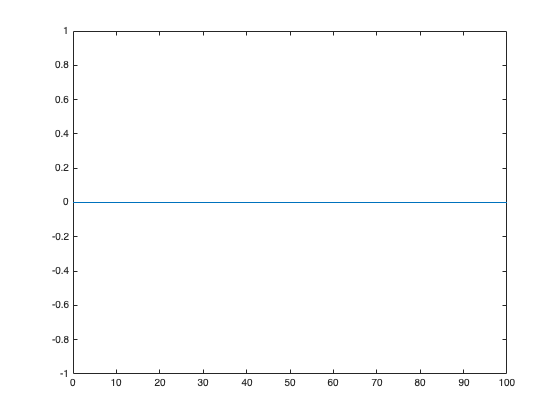


clear m1 m2 g l1 l2 t1 t2 t;
m1 = 4;
m2 = 2;
l1 = 10;
l2 = 4;
tau1 = 0;
tau2 = 0;
g = 9.81;
dt = (0:0.05:100);
%theta1 theta2 omega1 omega2
x0 =[pi/2,0,0,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(Y,t)sistema(Y,t,m1,m2,l1,l2,tau1,tau2),dt,x0,opts);
%Calcolo delle traiettorie:
x_m1 = l1.*cos(x(:,1));
y_m1 = l1.*sin(x(:,1));
x_m2 = l1.*cos(x(:,1))+l2.*cos(x(:,1)+x(:,3));
y_m2 = l1.*sin(x(:,1))+l2.*sin(x(:,1)+x(:,3));

figure;
plot(t,x(:,1));

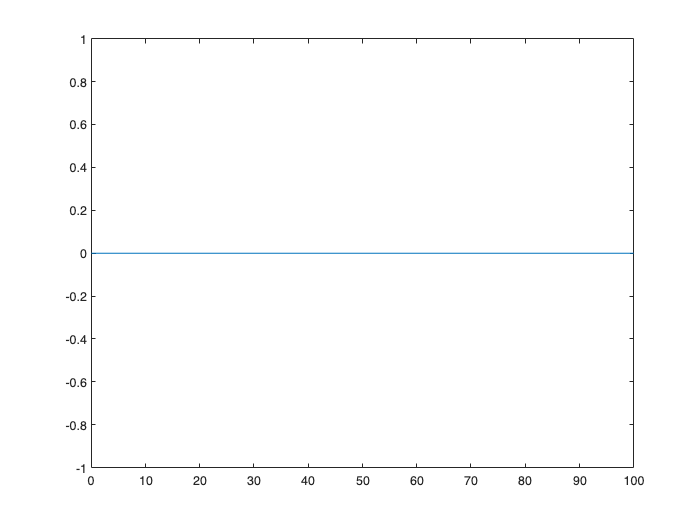

figure;
plot(t,x(:,3));

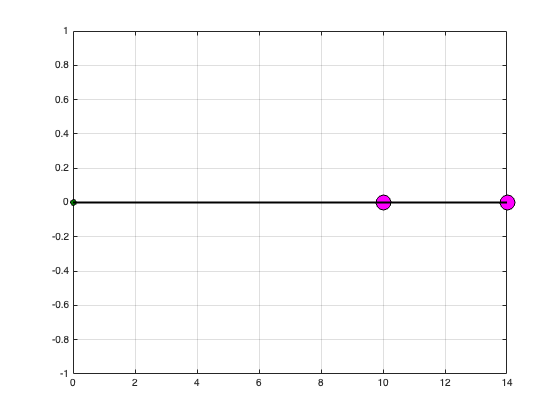



for i = 1:2001
 pause(0.001)
 plot(0,0,'o','MarkerFaceColor','[0, 0.5, 0]','MarkerEdgeColor','black');
 hold on;
 %traiettoria
 plot(x_m1(1:i),y_m1(1:i),'b-','LineWidth',2);
 plot(x_m2(1:i),y_m2(1:i),'k-','LineWidth',2);
 %teste del cammino 
 plot(x_m1(i),y_m1(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 plot(x_m2(i),y_m2(i),'ko','MarkerFaceColor','magenta','MarkerEdgeColor','black','MarkerSize',15);
 %aste
 plot([0; x_m1(i)], [0;y_m1(i)],'color','k','LineWidth',2);
 plot([x_m1(i); x_m2(i)], [y_m1(i);y_m2(i)], 'color','k','LineWidth',2);
 grid on;  
end